# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


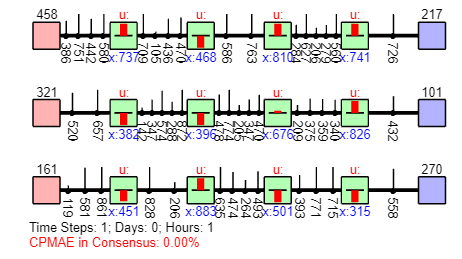

Figure saved as Results\PaperFigures\InitNetCase2.png and Results\PaperFigures\InitNetCase2.fig


net.setInitialErrors();


% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal;  axis off;
net.draw(1);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 7;
fileName = ['InitNetCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


tMax = 24*30 % 4 weeks

tMax = 720

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display


% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)
% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks

d1 = 0;
d2 = -0; %-10
d3 = 1;
d4 = 0;
d5 = 1;
d6 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit] = net.findBestParameters(matFile,d1,d2,d3,d4,d5,d6) 

Error in c:
    0.2572   11.8655    0.0118       Inf    0.4036    0.1358

Best parameter combination found:
Minimum objective value: 0.81347
pVal: 0.1
deltaCostCoef: 316.2278
gammaCostCoef: 1000
comCostLimit: 0.0031623
LNorm: 1.3322
KNorm: 0.031596
gammaTilde: 210.3225
KLinks: 101
JCon: 24.5364
JTra: 44.4732


pVal = 0.1000

deltaCostCoef = 316.2278

gammaCostCoef = 1000

comCostLimit = 0.0032


% d = [3.1623  0.0010  1.0000  0.1000];
% d = [0.0316    1000    100    0.01];
% d = [0.06    1000    100    0.01];
d = [0.0316, 1000, 100, 0.01]

d = 1.0e+03 *

    0.0000    1.0000    0.1000    0.0000


pVal = d(1)

pVal = 0.0316

deltaCostCoef = d(2)

deltaCostCoef = 1000

gammaCostCoef = d(3) %100

gammaCostCoef = 100

comCostLimit = d(4)

comCostLimit = 0.0100


save(['tempNet',num2str(caseNum)])
perfData.cumVals = [];
perfData.conHist = [];
perfData.traHist = [];
perfData.cumConHist = [];
perfData.cumTraHist = [];
perfData.caseName{1} = 'CaseNames';
save('caseNum.mat','caseNum','perfData')

Local Steady State Control (LSSC): K = 0, L = 0

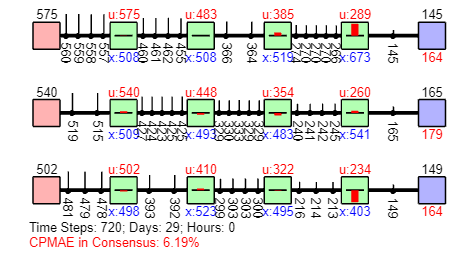

Figure saved as Results\PaperFigures\FinalNetCase2LSSC.png and Results\PaperFigures\FinalNetCase2LSSC.fig


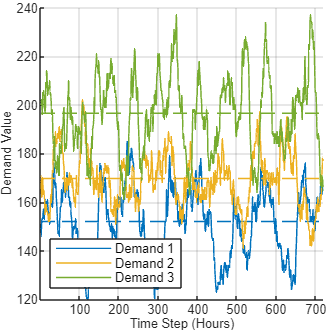

Figure saved as Results\PaperFigures\DemandsCase2.png and Results\PaperFigures\DemandsCase2.fig


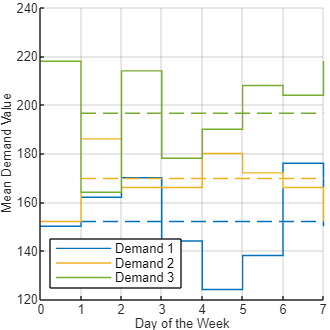

Figure saved as Results\PaperFigures\MeanDemandsCase2.png and Results\PaperFigures\MeanDemandsCase2.fig


clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'LSSC';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal;
net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum); 
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    net.computeErrorHistory();

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),tagVal];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

    % % % Performance plot
    % figNum = figNum + 1;
    % f = figure(figNum);
    % hold on; grid on;
    % net.plotNetworkPerformance();
    % close(f);

    % % Demand Profile
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on; 
    net.plotDemandProfiles();
    axis([-inf,inf,120,240]);

    % Save Fig
    figWidth = 2.5; figHeight = 2.5; fontSize = 7;
    fileName = ['DemandsCase',num2str(caseNum)];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


    % % Mean Demand Proile
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotMeanDemandProfiles();
    axis([-inf,inf,120,240]);

    % Save Fig
    figWidth = 2.5; figHeight = 2.5; fontSize = 7;
    fileName = ['MeanDemandsCase',num2str(caseNum)];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.cumConHist = [perfData.cumConHist; net.cumMeanAbsConErrorHistory];
perfData.cumTraHist = [perfData.cumTraHist; net.cumMeanAbsTraErrorHistory];
perfData.caseName{end + 1} = tagVal;
save('caseNum.mat','caseNum','perfData')

Local State Feedback Control (LSFC): K = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'LSFC';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.5830   -0.6748   -0.7289   -0.5919   -0.6494   -0.6954   -0.6363   -0.7517   -0.8093   -0.8103   -0.8950   -0.9454   -1.0114   -0.6578   -0.7284   -0.8086
    0.0221   -0.3972   -0.3566   -0.3197    0.0306   -0.0829   -0.1987   -0.4431   -0.4352   -0.3967   -0.4312   -0.4841   -0.5175   -0.3559   -0.3816   -0.4490
   -0.1766   -0.0675   -0.3904   -0.3041   -0.1968   -0.2078   -0.2082   -0.0703   -0.1703   -0.4349   -0.4622   -0.4850   -0.4443   -0.3369   -0.3939   -0.4372
   -0.0982   -0.1325    0.0509   -0.2766   -0.1097   -0.1119   -0.1156   -0.1484   -0.1436    0.0628   -0.0524   -0.1363   -0.1750   -0.3083   -0.3264   -0.2845


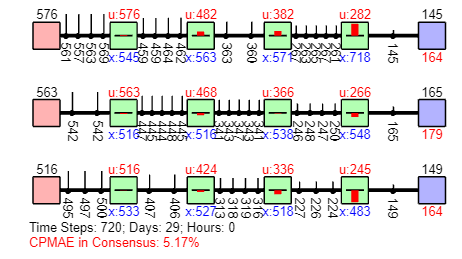

Figure saved as Results\PaperFigures\FinalNetCase2LSFC.png and Results\PaperFigures\FinalNetCase2LSFC.fig


net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum);
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    net.computeErrorHistory();

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),tagVal];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

    % % Performance plot
    % figNum = figNum + 1;
    % f = figure(figNum);
    % hold on; grid on;
    % net.plotNetworkPerformance();
    % close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.cumConHist = [perfData.cumConHist; net.cumMeanAbsConErrorHistory];
perfData.cumTraHist = [perfData.cumTraHist; net.cumMeanAbsTraErrorHistory];
perfData.caseName{end + 1} = tagVal;
save('caseNum.mat','caseNum','perfData')

Global Consensus Control ( with L = 0 )

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'GCC';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.globalConsensusControlDesign();
net.KGlobal

ans =     0.0002    0.0019   -0.0007    0.0002    0.0019   -0.0011   -0.0011   -0.0007   -0.0007   -0.0007    0.0019   -0.0011
    0.4109   -0.0472   -0.0342   -0.0391   -0.0472   -0.0311   -0.0311   -0.0342   -0.0342   -0.0342   -0.0472   -0.0311
   -0.0394    0.4027   -0.0345   -0.0394   -0.0473   -0.0305   -0.0305   -0.0345   -0.0345   -0.0345   -0.0473   -0.0305
   -0.0392   -0.0480    0.4158   -0.0392   -0.0480   -0.0303   -0.0303   -0.0342   -0.0342   -0.0342   -0.0480   -0.0303
    0.0002    0.0038   -0.0012    0.0002    0.0038   -0.0023   -0.0023   -0.0012   -0.0012   -0.0012    0.0038   -0.0023
   -0.0394   -0.0478   -0.0343   -0.0394    0.4022   -0.0302   -0.0302   -0.0343   -0.0343   -0.0343   -0.0478   -0.0302
   -0.0391   -0.0480   -0.0341   -0.0391   -0.0480    0.4196   -0.0304   -0.0341   -0.0341   -0.0341   -0.0480   -0.0304
   -0.0391   -0.0475   -0.0343   -0.0391   -0.0475   -0.0307    0.4193   -0.0343   -0.0343   -0.0343   -0.0475   -0.0307
    0.0003    0.0019   -0.

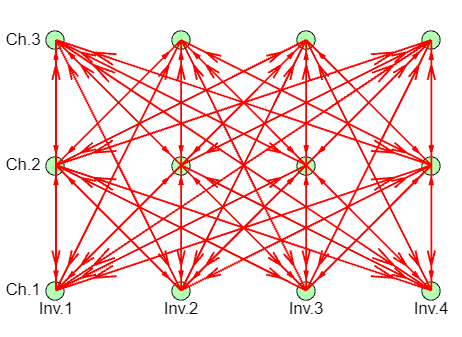

Figure saved as Results\PaperFigures\TopologyCase2GCC.png and Results\PaperFigures\TopologyCase2GCC.fig


net.setAdjointMatrixAndNeighborsAndControllers();

% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 9;
fileName = ['TopologyCase',num2str(caseNum),tagVal];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

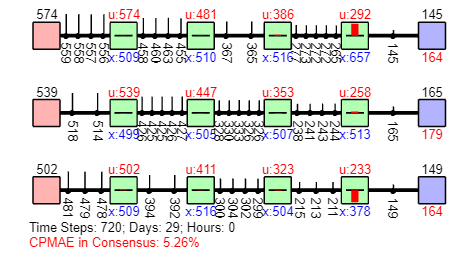

Figure saved as Results\PaperFigures\FinalNetCase2GCC.png and Results\PaperFigures\FinalNetCase2GCC.fig



% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    net.computeErrorHistory();

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),'GCC'];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);
    
    % % Performance plot
    % figNum = figNum + 1;
    % f = figure(figNum);
    % hold on; grid on;
    % net.plotNetworkPerformance();
    % close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.cumConHist = [perfData.cumConHist; net.cumMeanAbsConErrorHistory];
perfData.cumTraHist = [perfData.cumTraHist; net.cumMeanAbsTraErrorHistory];
perfData.caseName{end + 1} = tagVal;
save('caseNum.mat','caseNum','perfData')

Distributed Control with Hard Graph Constraints

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'DCC-C';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3341

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.7839

KNormVal = 2.0287e-05

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.2548   -0.2325   -0.1978   -0.1558   -0.2832   -0.3083   -0.3375   -0.2584   -0.2771   -0.2198   -0.2406   -0.2589   -0.2727   -0.1731   -0.1921   -0.2110
    0.2537   -0.2134   -0.1449   -0.1125    0.2820    0.0948    0.0219   -0.2371   -0.2591   -0.1610   -0.1713   -0.1813   -0.2005   -0.1250   -0.1347   -0.1451
   -0.0204    0.1462   -0.1903   -0.1512   -0.0227   -0.0247   -0.0253    0.1625    0.0461   -0.2115   -0.2282   -0.2488   -0.2716   -0.1680   -0.1823   -0.1979
   -0.0166   -0.0264    0.1836   -0.2297   -0.0184   -0.0139   -0.0117   -0.0294   -0.0239    0.2041    0.0700    0.0112   -0.0118   -0.2552   -0.2704   -0.2915


net.KGlobal

ans = 1.0e-04 *

         0         0         0         0         0         0         0         0         0         0         0         0
    0.0194    0.0093   -0.0036         0   -0.0159   -0.0038   -0.0003         0         0   -0.0051         0         0
   -0.0009    0.0196    0.0097   -0.0034         0   -0.0159   -0.0036   -0.0005         0         0   -0.0049         0
         0   -0.0011    0.0191    0.0071         0         0   -0.0159   -0.0032         0         0         0   -0.0060
         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0044   -0.0017   -0.0012         0    0.1375   -0.0876   -0.0062         0   -0.0341   -0.0022         0         0
         0   -0.0048   -0.0026   -0.0020    0.0024    0.1373   -0.0884   -0.0017         0   -0.0347   -0.0036   -0.0020
         0         0   -0.0109   -0.0177         0    0.0003    0.1158   -0.0200         0         0   -0.0426   -0.0248
         0     

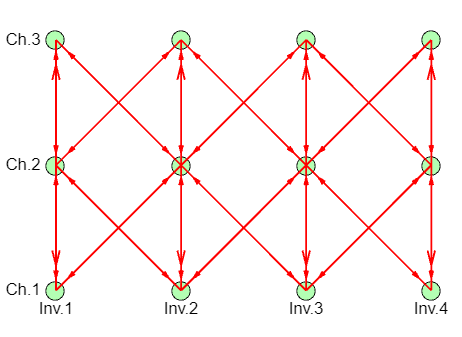

Figure saved as Results\PaperFigures\ReferenceTopologyCase2.png and Results\PaperFigures\ReferenceTopologyCase2.fig



% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMatRef);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 9;
fileName = ['ReferenceTopologyCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

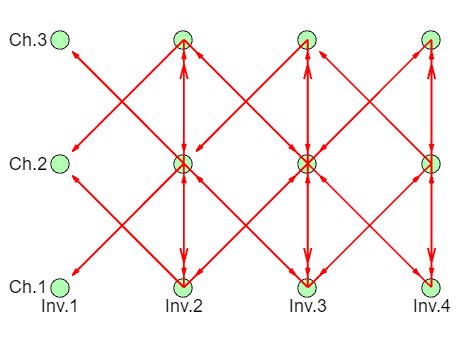

Figure saved as Results\PaperFigures\TopologyCase2DCC-C.png and Results\PaperFigures\TopologyCase2DCC-C.fig




% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 10;
fileName = ['TopologyCase',num2str(caseNum),tagVal];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

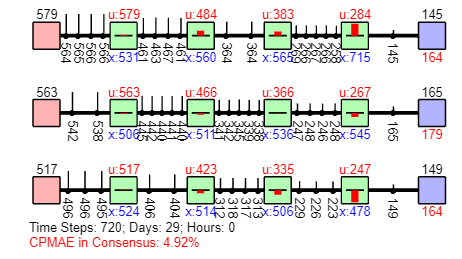

Figure saved as Results\PaperFigures\FinalNetCase2DCC-C.png and Results\PaperFigures\FinalNetCase2DCC-C.fig




% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    net.computeErrorHistory();

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),tagVal];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);
    
    % % Performance plot
    % figNum = figNum + 1;
    % f = figure(figNum);
    % hold on; grid on;
    % net.plotNetworkPerformance();
    % close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.cumConHist = [perfData.cumConHist; net.cumMeanAbsConErrorHistory];
perfData.cumTraHist = [perfData.cumTraHist; net.cumMeanAbsTraErrorHistory];
perfData.caseName{end + 1} = tagVal;
save('caseNum.mat','caseNum','perfData')

Distributed Control with Soft Graph Constraints

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'DCC-U';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3341

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.7839

KNormVal = 0.0737

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.2548   -0.2325   -0.1978   -0.1558   -0.2832   -0.3083   -0.3375   -0.2584   -0.2771   -0.2198   -0.2406   -0.2589   -0.2727   -0.1731   -0.1921   -0.2110
    0.2537   -0.2134   -0.1449   -0.1125    0.2820    0.0948    0.0219   -0.2371   -0.2591   -0.1610   -0.1713   -0.1813   -0.2005   -0.1250   -0.1347   -0.1451
   -0.0204    0.1462   -0.1903   -0.1512   -0.0227   -0.0247   -0.0253    0.1625    0.0461   -0.2115   -0.2282   -0.2488   -0.2716   -0.1680   -0.1823   -0.1979
   -0.0166   -0.0264    0.1836   -0.2297   -0.0184   -0.0139   -0.0117   -0.0294   -0.0239    0.2041    0.0700    0.0112   -0.0118   -0.2552   -0.2704   -0.2915


net.KGlobal

ans =    -0.0422   -0.0022         0    0.0233   -0.0078         0         0    0.0155   -0.0040         0         0    0.0174
    0.0007   -0.0019         0         0    0.0002   -0.0001         0    0.0004    0.0001    0.0001         0    0.0005
    0.0003    0.0000   -0.0020    0.0006    0.0002         0         0    0.0001    0.0003    0.0001    0.0003    0.0001
    0.0003         0         0   -0.0007    0.0001    0.0001         0         0    0.0001         0         0    0.0001
   -0.0135         0         0    0.0114   -0.0197   -0.0005         0    0.0191   -0.0217         0         0    0.0248
         0         0         0         0    0.0002   -0.0002         0         0         0   -0.0001         0         0
         0         0         0         0         0    0.0001   -0.0001         0         0         0   -0.0001         0
    0.0001         0         0         0    0.0001         0         0   -0.0001    0.0001         0         0   -0.0002
   -0.0022         0      

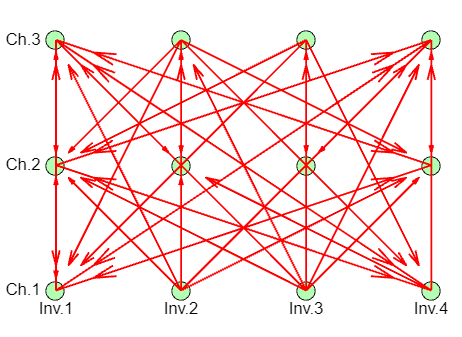

Figure saved as Results\PaperFigures\TopologyCase2DCC-U.png and Results\PaperFigures\TopologyCase2DCC-U.fig



% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off; 
net.plotConnections(net.adjMat);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 9;
fileName = ['TopologyCase',num2str(caseNum),tagVal];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

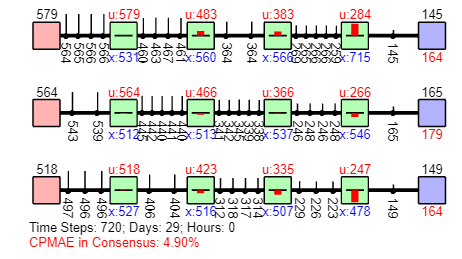

Figure saved as Results\PaperFigures\FinalNetCase2DCC-U.png and Results\PaperFigures\FinalNetCase2DCC-U.fig




% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    net.computeErrorHistory();

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),tagVal];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);
    
    % % Performance plot
    % figNum = figNum + 1;
    % f = figure(figNum);
    % hold on; grid on;
    % net.plotNetworkPerformance();
    % close(f);

end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.cumConHist = [perfData.cumConHist; net.cumMeanAbsConErrorHistory];
perfData.cumTraHist = [perfData.cumTraHist; net.cumMeanAbsTraErrorHistory];
perfData.caseName{end + 1} = tagVal;
save('caseNum.mat','caseNum','perfData')

% perfData.cumVals
% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)

Summary Plots (for the paper)

% A = [40.4448	26.9191; 34.4617	22.8563]
perfData.cumVals*100/500

ans =     7.6884    6.1913
   10.1035    5.1671
    7.2698    5.2558
    8.8684    4.9159
    9.0194    4.8979



close all
clc

conHist = perfData.conHist;
traHist = perfData.traHist;
cumConHist = perfData.cumConHist;
cumTraHist = perfData.cumTraHist;
caseNames = perfData.caseName;
numCases = size(conHist,1);

L = size(conHist,2);

figNum = figNum + 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:numCases
    plot(1:L, conHist(k,:), '-', 'LineWidth', 0.8,  'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t)); 
end
axis([0,L,0,40])
xlabel('Time Step (Hours)');
ylabel('PMAE in Consensus (%)');
legend('Location', 'northeast'); 
percentageImprovement = sum(conHist(1,:)>=conHist(end,:))*100/L

percentageImprovement = 81.3889

percentageImprovement = sum(conHist(2,:)>=conHist(end,:))*100/L

percentageImprovement = 52.2222

percentageImprovement = sum(conHist(3,:)>=conHist(end,:))*100/L

percentageImprovement = 57.2222

percentageImprovement = sum(conHist(4,:)>=conHist(end,:))*100/L

percentageImprovement = 64.1667

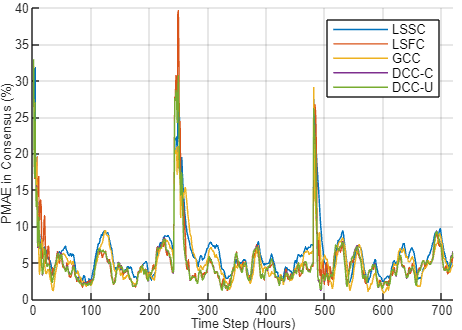

Figure saved as Results\PaperFigures\ConPerfCase2.png and Results\PaperFigures\ConPerfCase2.fig



figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['ConPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);



figNum = figNum + 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:numCases
    plot(1:L, cumConHist(k,:), '-', 'LineWidth', 0.8,  'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t)); 
end
axis([0,L,0,40])
xlabel('Time Step (Hours)');
ylabel('CPMAE in Consensus (%)');
legend('Location', 'northeast'); 
percentageImprovement = sum(cumConHist(1,:)>=cumConHist(end,:))*100/L

percentageImprovement = 100

percentageImprovement = sum(cumConHist(2,:)>=cumConHist(end,:))*100/L

percentageImprovement = 99.4444

percentageImprovement = sum(cumConHist(3,:)>=cumConHist(end,:))*100/L

percentageImprovement = 96.8056

percentageImprovement = sum(cumConHist(4,:)>=cumConHist(end,:))*100/L

percentageImprovement = 97.0833

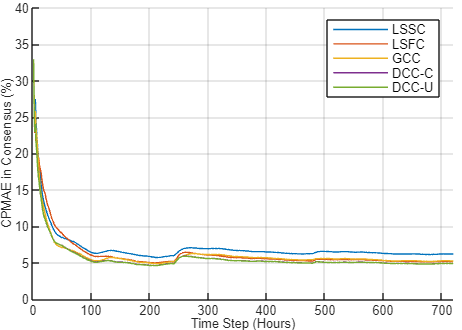

Figure saved as Results\PaperFigures\CumConPerfCase2.png and Results\PaperFigures\CumConPerfCase2.fig




figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['CumConPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);



cumConHist(:,end)

ans =     6.1913
    5.1671
    5.2558
    4.9159
    4.8979



% 
% 
% figNum = figNum + 1;
% figure(figNum);
% hold on; grid on; axis tight;
% for k = 1:numCases
%     plot(1:L, traHist(k,:), '-', 'LineWidth', 0.8, 'DisplayName', caseNames{k+1});
%     % title(sprintf('Performance Metrics at Time Step %d', t));     
% end
% axis([0,L,0,80])
% xlabel('Time Step (Hours)');
% ylabel('Mean Perc. Abs. Tracking Error (%)');
% legend('Location', 'northeast'); 
% percentageImprovement = sum(traHist(1,:)>=traHist(end,:))*100/L
% percentageImprovement = sum(traHist(2,:)>=traHist(end,:))*100/L
% percentageImprovement = sum(traHist(3,:)>=traHist(end,:))*100/L
% 
% figWidth = 3.5; figHeight = 2.5; fontSize = 7;
% fileName = ['TraPerfCase',num2str(caseNum)];
% net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


% 
% figNum = figNum + 1;
% figure(figNum);
% hold on; grid on; axis tight;
% for k = 1:numCases
%     plot(1:L, cumTraHist(k,:), '-', 'LineWidth', 0.8, 'DisplayName', caseNames{k+1});
%     % title(sprintf('Performance Metrics at Time Step %d', t));     
% end
% axis([0,L,0,80])
% xlabel('Time Step (Hours)');
% ylabel('Cum. Mean Perc. Abs. Tracking Error (%)');
% legend('Location', 'northeast'); 
% percentageImprovement = sum(cumTraHist(1,:)>=cumTraHist(end,:))*100/L
% percentageImprovement = sum(cumTraHist(2,:)>=cumTraHist(end,:))*100/L
% percentageImprovement = sum(cumTraHist(3,:)>=cumTraHist(end,:))*100/L
% 
% figWidth = 3.5; figHeight = 2.5; fontSize = 7;
% fileName = ['CumTraPerfCase',num2str(caseNum)];
% net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);
% 
% 
% net.printDefaultProperties()